format shortG
u = symunit;
% separateUnits(x)
% unitConvert(expr,units)


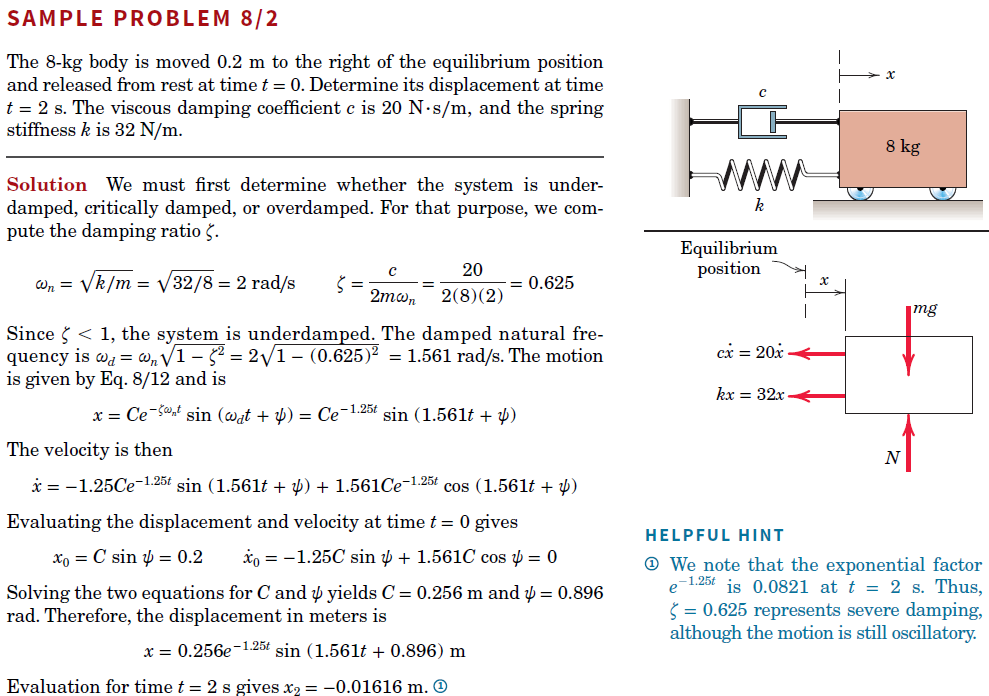

Vi kontroller først hvilken form for dæmpning vi har 

clear 

disp('Vi opstiller vores data')

Vi opstiller vores data


k = 32; % N/m    %* u.N / u.m
m = 8; % kg      %* u.kg
c = 20; %N*s/m   %* u.N * u.s / u.m
t0 = 0; %s       % Start tiden 
t1 = 2;          % Slut tiden
disp('Egensvingningen findes')

Egensvingningen findes


w_n = sqrt(k/m) %egensvingningen

w_n =      2


disp('Dæmpningsrationen findes')

Dæmpningsrationen findes


zeta = c/(2 * m * w_n) % viscous damping factor or damping ratio

zeta =         0.625



if separateUnits(zeta) < 1
    disp('systemet er underdamped')
elseif separateUnits(zeta) == 1
    disp('systemet er critical damped')
else
    disp('systemet er overdamped')
end

systemet er underdamped


disp('Finder den naturlige dæmpnings frekvens')

Finder den naturlige dæmpnings frekvens


w_d = w_n*sqrt(1-zeta^2) % damped natrual freqancy

w_d =        1.5612


syms psi C_s f(t) t f_1(t)
disp('Værdierne ved t = 0 findes for sted og hastighedsfunktionen')

Værdierne ved t = 0 findes for sted og hastighedsfunktionen


x_0 = 0.2; % m %start stedet
V_0 = 0; % m/s %start hastigheden

disp('Ligning (8/12) opstilles og benyttes til at finde forskydningen')

Ligning (8/12) opstilles og benyttes til at finde forskydningen


f(t) = C_s * exp(-zeta * w_n * t) * (sin(w_d * t + psi)) % Sted funktionen for underdæmpede svininger ligning (8/12) %

$$f(t) = C_{s}\,{\mathrm{e}}^{-\frac{5\,t}{4}}\,\sin\left(\psi +\frac{\sqrt{39}\,t}{4}\right)$$


disp('Ved at differentier forskydningsligningen får vi hastighedes ligningen')

Ved at differentier forskydningsligningen får vi hastighedes ligningen


f_1(t) = diff(f(t), t) %% Hastigheds funktionen

$$f\_1(t) = \frac{\sqrt{39}\,C_{s}\,{\mathrm{e}}^{-\frac{5\,t}{4}}\,\cos\left(\psi +\frac{\sqrt{39}\,t}{4}\right)}{4}-\frac{5\,C_{s}\,{\mathrm{e}}^{-\frac{5\,t}{4}}\,\sin\left(\psi +\frac{\sqrt{39}\,t}{4}\right)}{4}$$


disp('Vi løser ligningssystemet for C_s og psi')

Vi løser ligningssystemet for C_s og psi


x = [f(t0) == x_0, f_1(t0) == V_0]; %% sættes op i et array så der kan solves for de 2 ukendte. 
% start værdiger t = 0 x = 0.2 osv hastighed er 0 når t = 0

S = solve(x, psi, C_s); %Solver for psi og C_s i vores x lignings system


%udpakker og vudere værdierne fra struct
psi = vpa(S.psi, 5) %Vpa

$$psi = \left(\begin{array}{c} -2.2459\\ 0.89566 \end{array}\right)$$

C_s = vpa(S.C_s, 5) %Vpa

$$C\_s = \left(\begin{array}{c} -0.25621\\ 0.25621 \end{array}\right)$$


fprintf('Vi erstatter C_s og psi i forskydningsligningen \nog finder restultatet t = %f', t0)

Vi erstatter C_s og psi i forskydningsligningen 
og finder restultatet t = 0.000000

f(t) = C_s(2)*exp(-zeta * w_n * t)*(sin(w_d * t + psi(2))); % Indsætter vores nye værdiger i funktionenn så vi for en real ligning (2) er for at få det korrekte indeks 
fprintf('Placeringen af kassen til tiden t = %f er således:', t1)

Placeringen af kassen til tiden t = 2.000000 er således:

x_2 = vpa(f(t1), 3)

$$x\_2 = -0.0162$$


disp('Der plottes en kurve over bevægelsen')

Der plottes en kurve over bevægelsen


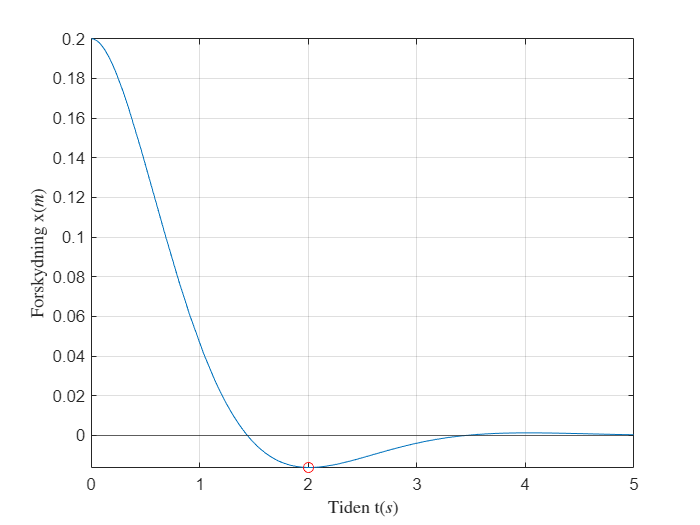

fplot(f(t), [t0, t1 + 3]) %plot 
hold on
% yline(double(x_2), '--r')
plot(t1, double(x_2), 'or')
xline(0)
yline(0)
ylabel('Forskydning x($m$)', Interpreter='latex')
xlabel('Tiden t($s$)', Interpreter='latex')
grid()
hold off